experimentPath = "../data/type1/355/";
% experimentPath = "../../static/experiment/type1/355/";
Fs = 44100;
fBegin = 2000;
fEnd = 6000;
m2s1 = 0.00;
m2s2 = 0.00;
soundSpeed = 347;

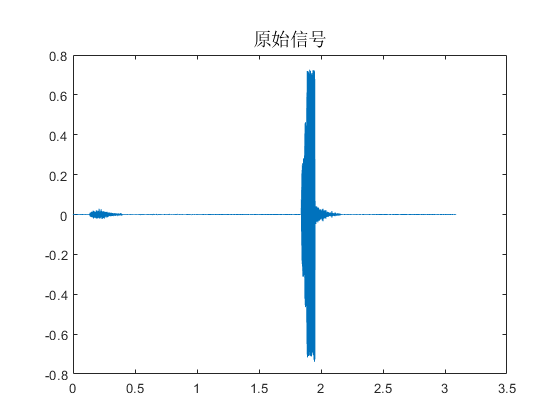

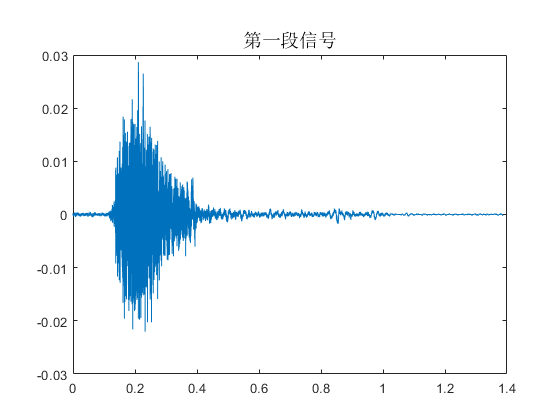

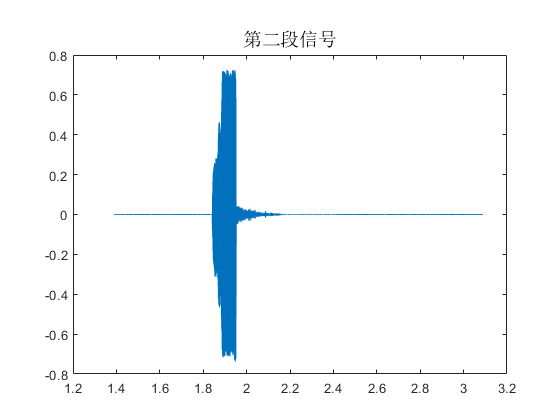

% 读取文件并获取第一段信号
[origin, ~] = audioread(experimentPath + "chirp.wav");
[received, ~] = audioread(experimentPath + "A_to_Z.wav");
received = received(4000:length(received));
[s1, s2, cutPoint] = cut_received_signal(received, origin, Fs);

s1 = s2

s1 =    -0.0002
   -0.0002
   -0.0002
   -0.0002
   -0.0002
   -0.0002
   -0.0002
   -0.0002
   -0.0002
   -0.0002


    0.4535



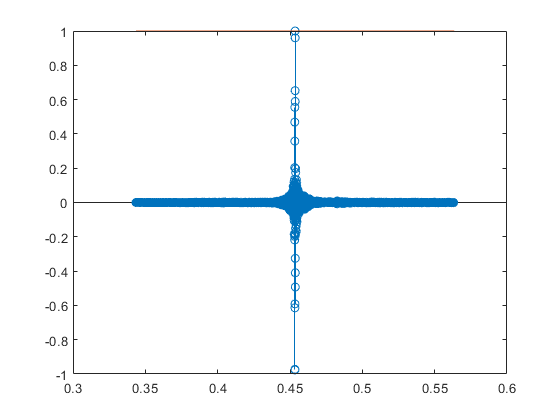

c_mean =     0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001


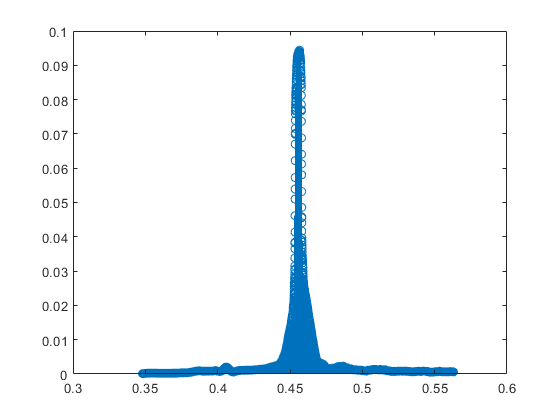

normalizec_c =     1.2252
   -0.8381
   -1.2335
   -1.6988
   -1.4601
   -0.9217
   -0.8299
   -0.9608
   -1.7339
   -2.3959


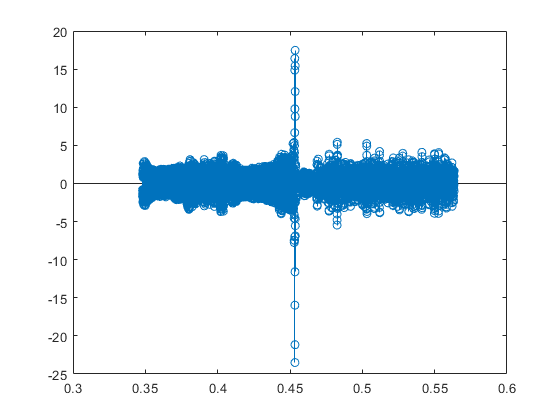

    0.4535



% 直接进行互相关
[c, lags] = xcorr(s1, origin);
lags = lags';
lags = lags / Fs;

% 归一化
[maxValue, ~] = max(abs(c));
c = c / maxValue;
% 过滤很靠近0的值
t = 0.0001;
c(c>=0&c<t)=t;
c(c<=0&c>-t)=-t;

[maxValue, maxIndex] = max(c);
% disp(lags(maxIndex, 1));
size = length(origin);
c = c(maxIndex-size:maxIndex+size);
lags = lags(maxIndex-size:maxIndex+size);

stem(lags, c);
hold on;
plot(lags, ones(size * 2 + 1, 1) * maxValue);
hold off;

% 窗口大小
W = 200;
core = ones(W + 1, 1) / W;
core(1,1) = 0;
c_mean = conv(abs(c), core, 'valid');
stem(lags(W + 1:length(c)), c_mean);
normalizec_c = c(W + 1:length(c))./c_mean;
stem(lags(W + 1:length(c)), normalizec_c);
% [maxValue, maxIndex] = max(normalizec_c);
% disp(lags(maxIndex + 200, 1))

lags = lags(W + 1:length(c));
c = normalizec_c;

% 使用GCC-PHAT
[c, lags] = correlation_gcc_v2(s1, origin, Fs, fBegin, fEnd);

% 归一化
[maxValue, ~] = max(abs(c));
c = c / maxValue;

% c = abs(c)
[maxValue, maxIndex] = max(c);
disp(lags(maxIndex, 1));

    0.4535



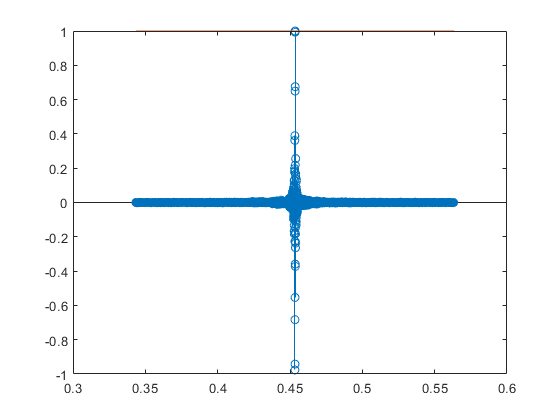

size = length(origin);
c = c(maxIndex-size:maxIndex+size);
lags = lags(maxIndex-size:maxIndex+size);


stem(lags, c);
hold on;
plot(lags, ones(size * 2 + 1, 1) * maxValue);
hold off;


% 窗口大小
W = 200;
core = ones(W + 1, 1) / W;
core(1,1) = 0;
c_mean = conv(abs(c), core, 'valid')

c_mean =     0.0005
    0.0005
    0.0005
    0.0005
    0.0005
    0.0005
    0.0005
    0.0005
    0.0005
    0.0005


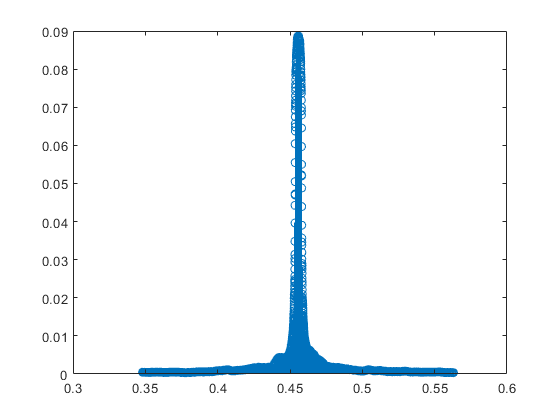

stem(lags(W + 1:length(c)), c_mean);

normalizec_c = c(W + 1:length(c))./c_mean

normalizec_c =     1.6802
   -0.0842
   -1.5688
   -2.1480
   -1.7755
   -0.9058
   -0.1334
    0.2019
    0.1735
    0.1202


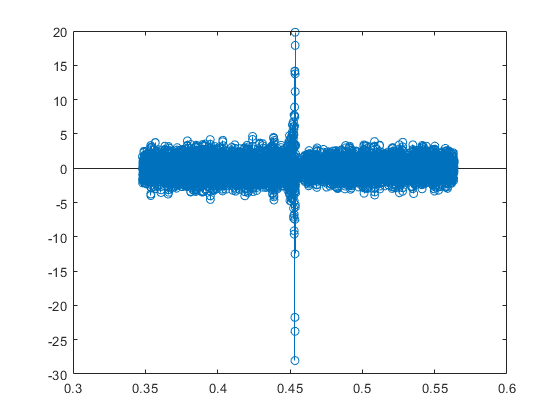

stem(lags(W + 1:length(c)), normalizec_c);

[maxValue, maxIndex] = max(normalizec_c);
disp(lags(maxIndex + 200, 1))

    0.4535

